# 第九章 图像与视频的质量评价

- 图像质量评价 Image Quality Assessment IQA

- 视频质量评价 Video Quality Assessment VQA

基于结构相似性(SSIM) 的全参考IQA的可执行MATLAB代码见(ssim.m)，请在MATLAB编程环境中调试执行,并测试质量预测的准确性和计算复杂度

## SSIM 函数测试与结果可视化代码

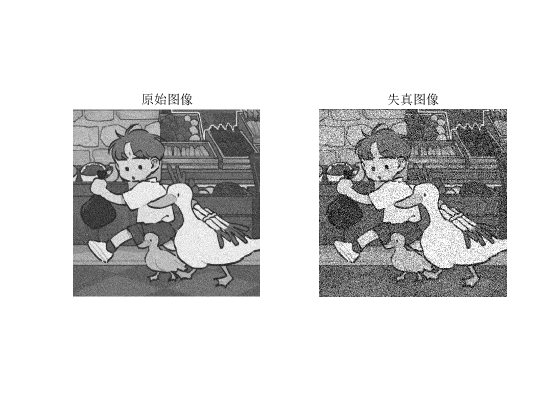

ref=imread('pappers.png');
ref=rgb2gray(ref);
ref=double(ref)/255;%归一化
test=imnoise(ref,'gaussian');
figure;
subplot(1,2,1);
imshow(ref);
title("原始图像");
subplot(1,2,2);
imshow(test);
title("失真图像");

使用MATLAB工具箱中的函数

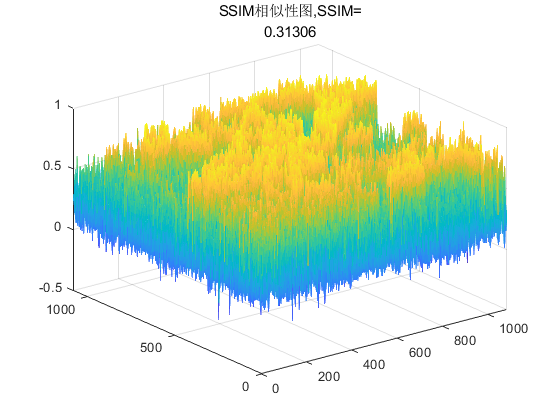

[mssim,ssim_map]=ssim(ref,test);
figure
mesh(ssim_map);
title(["SSIM相似性图,SSIM=",num2str(mssim)])

使用教材中的函数(文件ssim2.m)

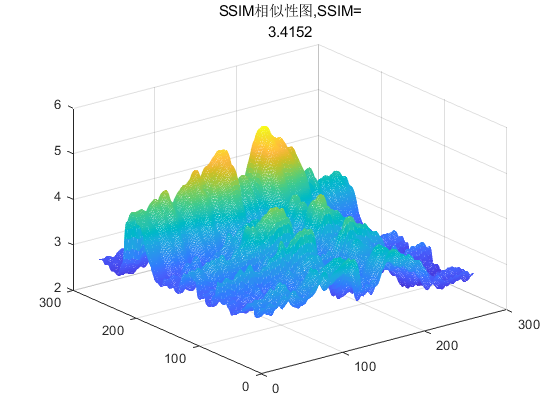

[mssim,ssim_map]=ssim2(ref,test);
figure
mesh(ssim_map);
title(["SSIM相似性图,SSIM=",num2str(mssim)])